`EE 150`

`Signals and Systems`

` Lab 2 System Analysis in Time Domain`

`Date Performed: 2022.10.13`

`Class Id: Thurs_Lab2`

`Name & ID: 王`鹏`豪 2021533138 周守琛 2021533042`

`1. `$y^{\prime \prime } \left(t\right)+3y^{\prime } \left(t\right)+6y\left(t\right)=6f^{\prime } \left(t\right)-8f\left(t\right),f\left(t\right)=e^{-t} u\left(t\right),y\left(0_- \right)=0,y^{\prime } \left(0_- \right)=10,y\left(0_+ \right)=0,y^{\prime } \left(0_+ \right)=6$`. Find out the zero-input response and plot it.`

clear;
clf;
syms y(t)
D2y = diff(y,t,2);
Dy = diff(y,t);
eqn1 = D2y+3*Dy+6*y==0;
conds = [y(0)==0, Dy(0)==10];
ysol = dsolve(eqn1, conds);
yzi = simplify(ysol)

$$yzi = \frac{4\,\sqrt{15}\,{\mathrm{e}}^{-\frac{3\,t}{2}}\,\sin\left(\frac{\sqrt{15}\,t}{2}\right)}{3}$$

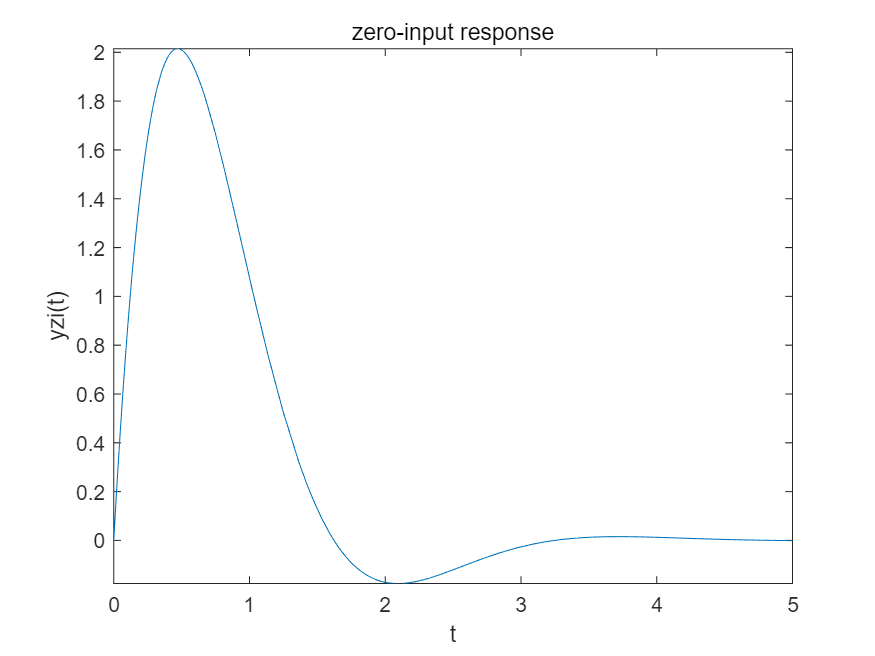

fplot(yzi, [0 5]);
xlabel("t");
ylabel("yzi(t)");
title("zero-input response");

`2. `$y^{\prime \prime } \left(t\right)+3y^{\prime } \left(t\right)+2y\left(t\right)=f^{\prime } \left(t\right)+3f\left(t\right),f\left(t\right)=e^{-3t} u\left(t\right)$`, find the unit impulse response with both ``impulse`` and`` lsim`` function.  Plot them in a 2*1 subplot.`

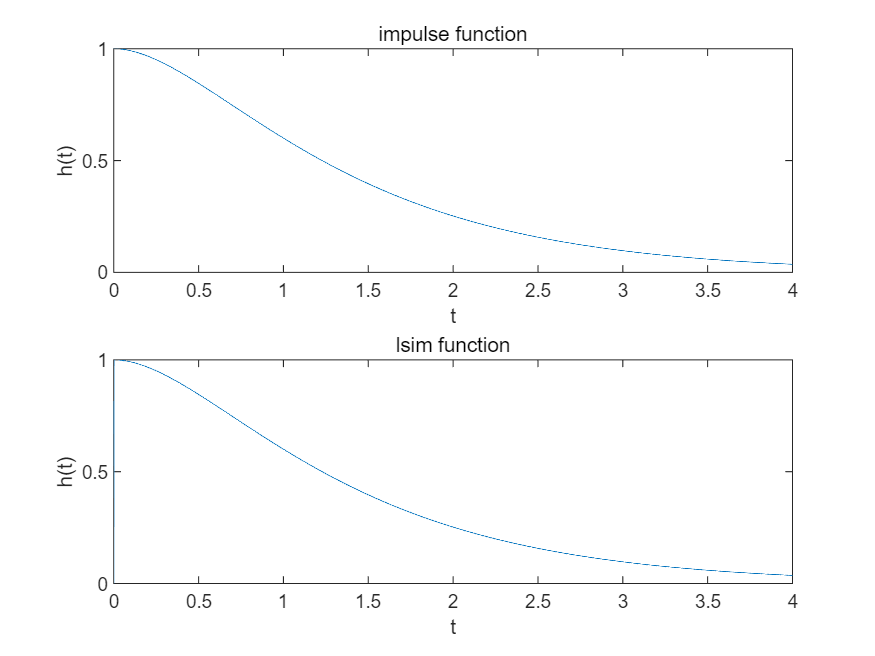

clear;
clf;
t = 0:0.001:5;
dt = 0.001;
sys = tf([1,3],[1,3,2]); 
h = impulse(sys,t);
subplot(2,1,1);
plot(t,h);
axis([0,4,0,1]);
xlabel("t");
ylabel("h(t)");
title('impulse function');

f = sign(dirac(t))/dt;
y = lsim(sys,f,t);
subplot(2,1,2);
plot(t,y);
axis([0,4,0,1]);
xlabel("t");
ylabel("h(t)");
title('lsim function');

`3. `$y^{\prime \prime } \left(t\right)+4y^{\prime } \left(t\right)+4y\left(t\right)=f^{\prime } \left(t\right)+3f\left(t\right)$`, where `$f\left(t\right)=e^{-t} u\left(t\right),y\left(0_- \right)=1,y^{\prime } \left(0_- \right)=0,y\left(0_+ \right)=0,y^{\prime } \left(0_+ \right)=1$`. Find out the zero-state response by solving differential equation, using function lsim and convolution. Compare the three results by plotting their result in a 3*1 subplot.`

clear;clf;
dt = 0.01;
t = 0:0.01:10;


syms y(t1)
D2y = diff(y,t1,2);
Dy = diff(y,t1);
f1 = (exp(-t1)*heaviside(t1));
Df = diff(f1, t1);
eqn1 = D2y+4*Dy+4*y==Df+3*f1;
conds = [y(0)==0, Dy(0)==1];
yzs = dsolve(eqn1, conds)

$$yzs = -\frac{{\mathrm{e}}^{-2\,t_{1}}\,\left(t_{1}-2\,{\mathrm{e}}^{t_{1}}+2\,\mathrm{sign}\left(t_{1}\right)-2\,{\mathrm{e}}^{t_{1}}\,\mathrm{sign}\left(t_{1}\right)-2\,t_{1}\,\mathrm{heaviside}\left(t_{1}\right)+3\,t_{1}\,\mathrm{sign}\left(t_{1}\right)+2\right)}{2}$$

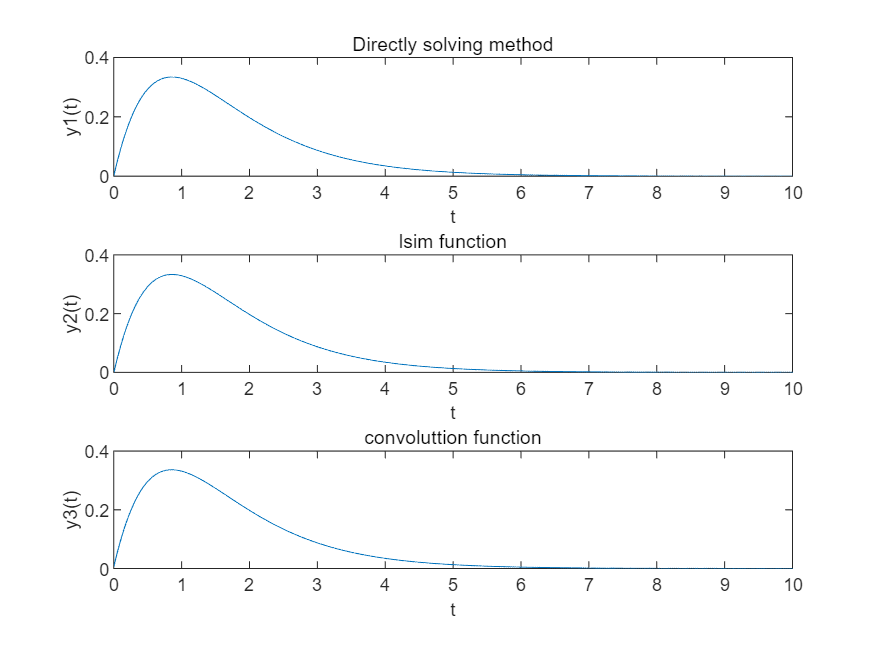

y1= double(subs(yzs,"t1",t));
subplot(3,1,1);
plot(t,y1);
xlabel("t");ylabel("y1(t)");title("Directly solving method");
axis([0 10 0 0.4])


sys = tf([1,3],[1,4,4]);
f = exp(-t).*heaviside(t);

y2 = lsim(sys, f, t);
subplot(3,1,2);
plot(t,y2);
xlabel("t");ylabel("y2(t)");title("lsim function");
axis([0 10 0 0.4])

h = impulse(sys, t);
y3 = conv(h, f)*dt;
n = length(y3);
tt = (0:n-1)*dt;
subplot(3,1,3);
plot(tt,y3);
xlabel("t");ylabel("y3(t)");title("convoluttion function");
axis([0 10 0 0.4])

`4. For the following circuit, `$R=3\Omega ,L=1H,C=0\ldotp 5F,x\left(t\right)=\sin \left(t\right)+\sin \left(20t\right)$`. The initial state of the circute is zero. `

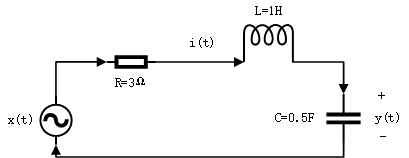

Tips: the circute can be described as:


$$\textrm{LC}\cdot y^{\prime \prime } \left(t\right)+\textrm{RC}\cdot y^{\prime } \left(t\right)+y\left(t\right)=x\left(t\right)$$


1)  `Following the tips, complete the differential equation describing the system.`

`2) Find out the full response of the system. Plot the result.`

clear;clf;
R = 3;
L = 1;
C = 0.5;
LC = L*C;
RC = R*C;

t1 = 0:0.01:20;

syms y(t);
D2y = diff(y, t, 2);
Dy = diff(y, t);
eqn1 = LC*D2y+RC*Dy+y == sin(t)+ sin(20*t)

$$eqn1(t) = \frac{\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)}{2}+\frac{3\,\frac{\partial }{\partial t}y\left(t\right)}{2}+y\left(t\right)=\sin\left(20\,t\right)+\sin\left(t\right)$$

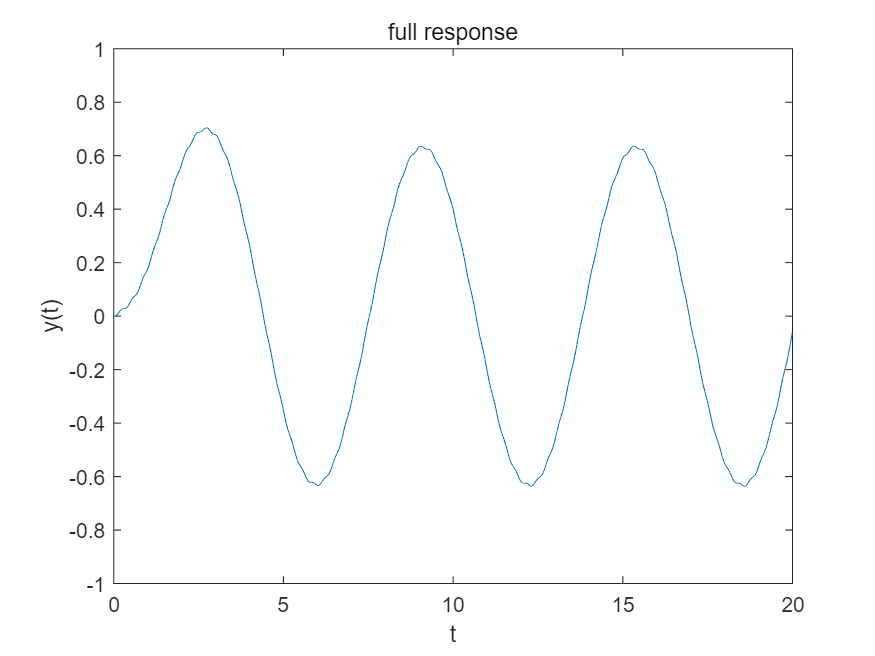

conds = [y(0)==0, Dy(0)==0];
ysol = dsolve(eqn1, conds);
yzs= double(subs(ysol,"t",t1));


eqn2 = LC*D2y+RC*Dy+y == 0;
ysol2 = dsolve(eqn2, conds);
yzi = double(subs(ysol2,"t",t1));

y = yzi + yzs;

plot(t1,y);
xlabel("t");ylabel("y(t)");title("full response");
axis([0 20 -1 1])

5.` Please implement the convolution function of the discrete sequence by yourself (do not use MATLAB build-in function for convolution). Use the your student ID as the inputs and display the convolution result.`

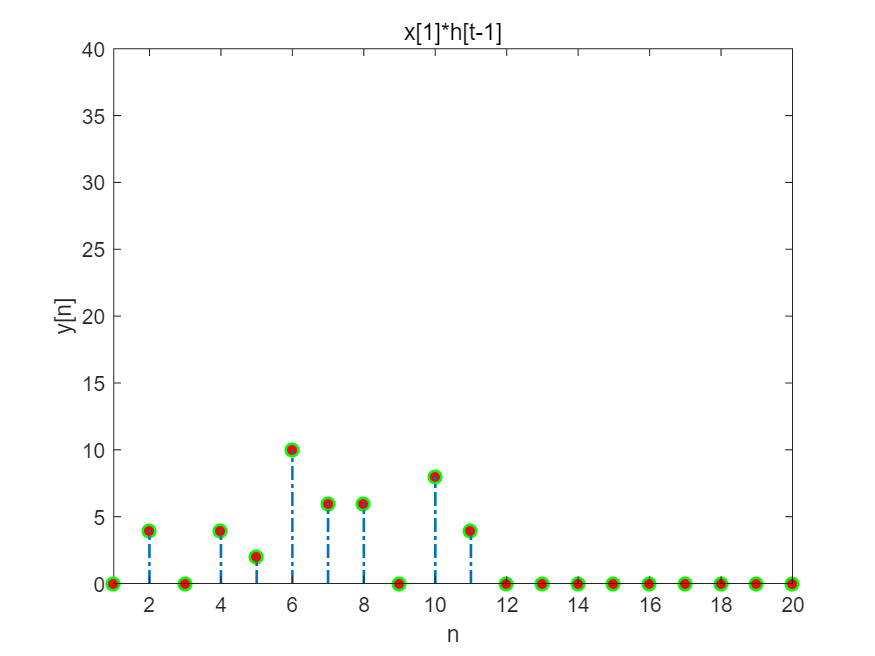

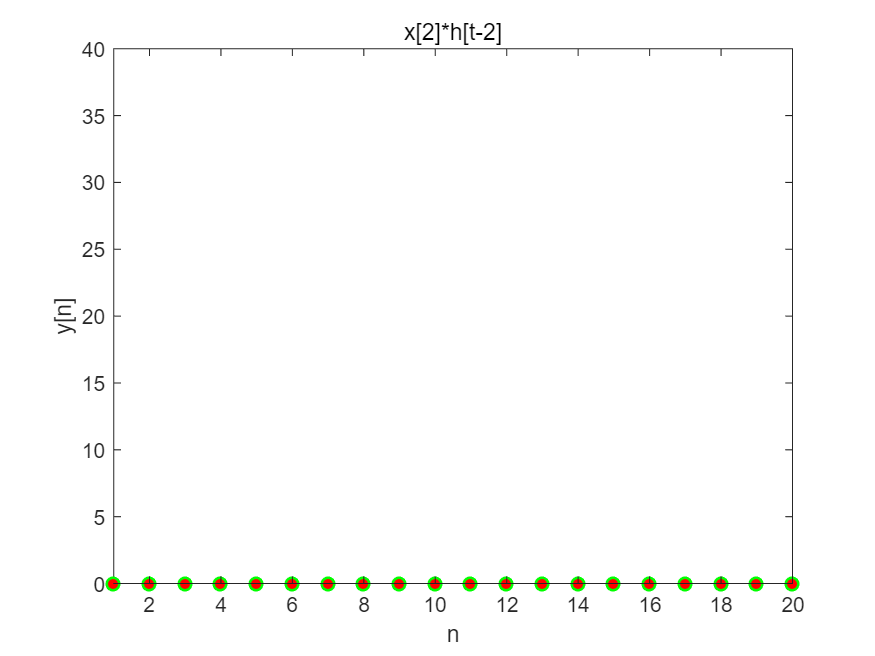

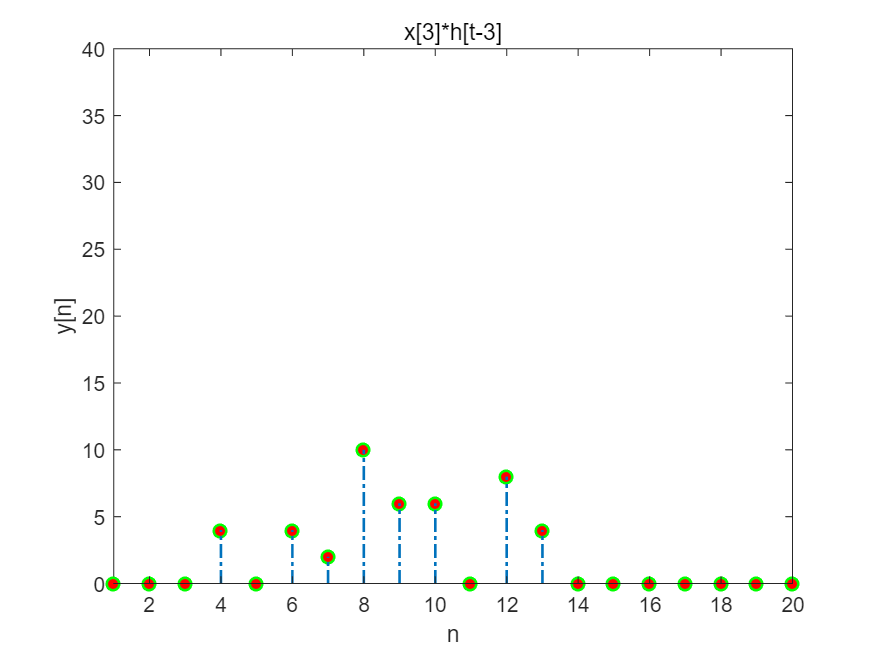

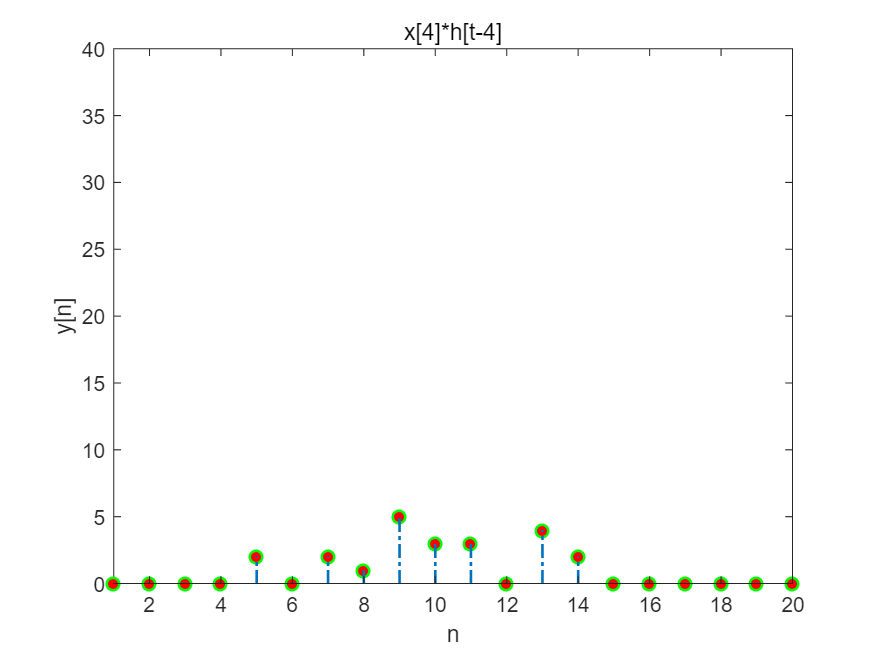

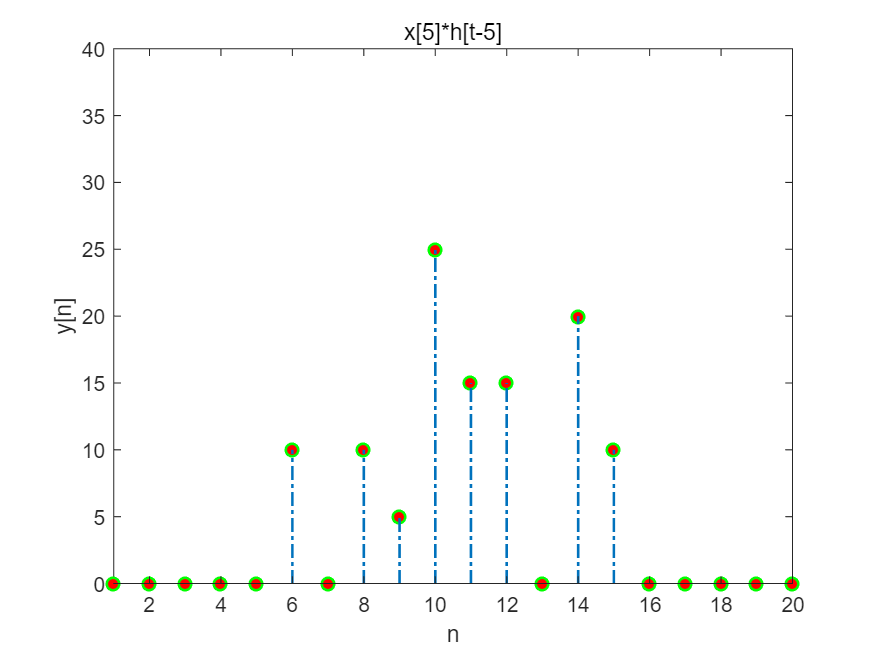

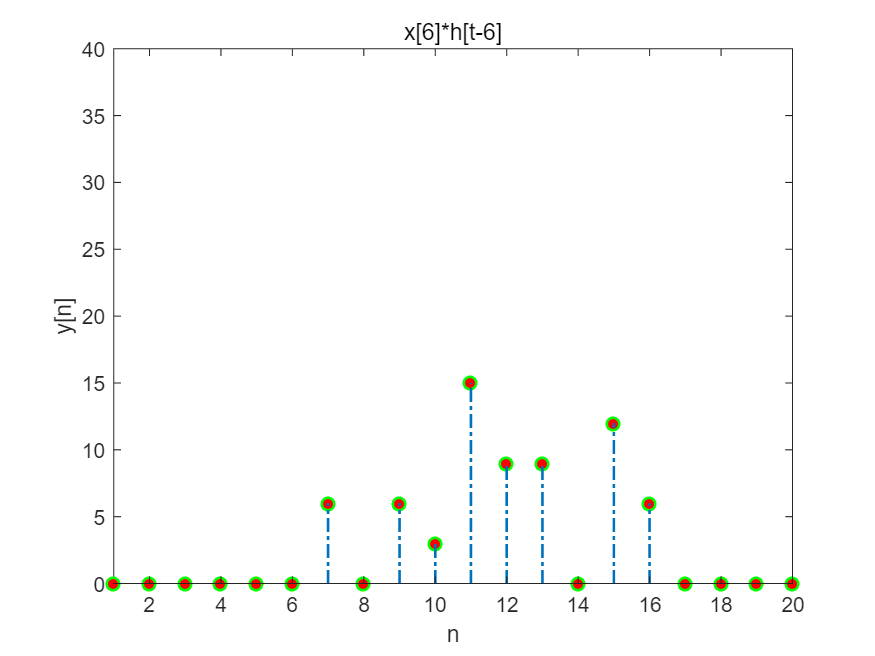

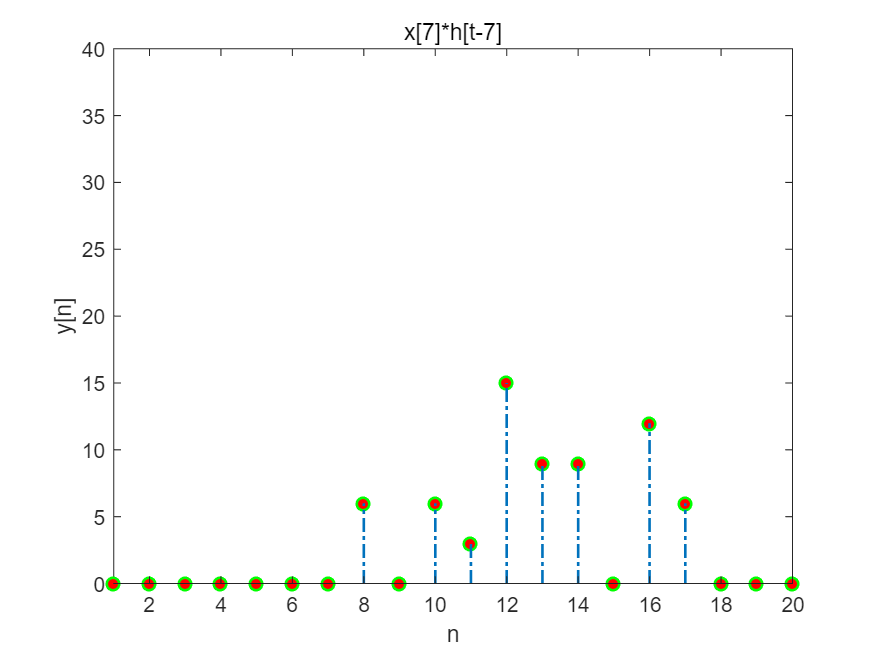

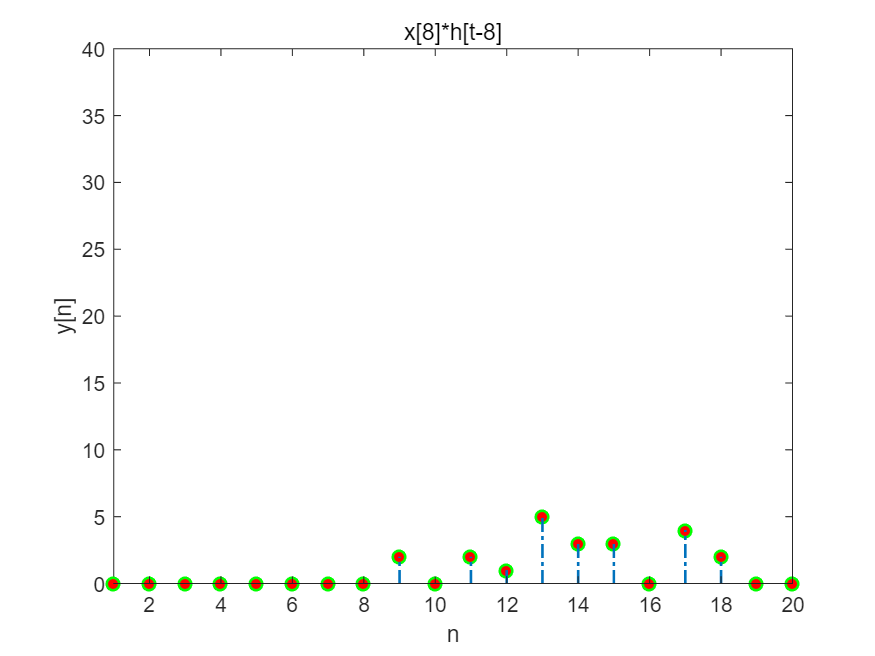

clear;
clf;
x = [2 0 2 1 5 3 3 1 3 8];
h = [2 0 2 1 5 3 3 0 4 2];
y=zeros(1,(length(x)+length(h)));
for i=(1:length(x))
    yi=zeros(1,(length(x)+length(h)));
    for j=(1:length(h))
        yi(i+j)=x(i)*h(j);
    end
    y=y+yi;
figure(i)
    stem((1:20),yi,'LineStyle','-.',...
    'LineWidth',1.25,...
     'MarkerFaceColor','red',...
     'MarkerEdgeColor','green') ; 
    axis([1,20,0,40]);
    xlabel("n");
    ylabel("y[n]");
    title("x["+num2str(i)+"]*h[t-"+num2str(i)+"]");
end

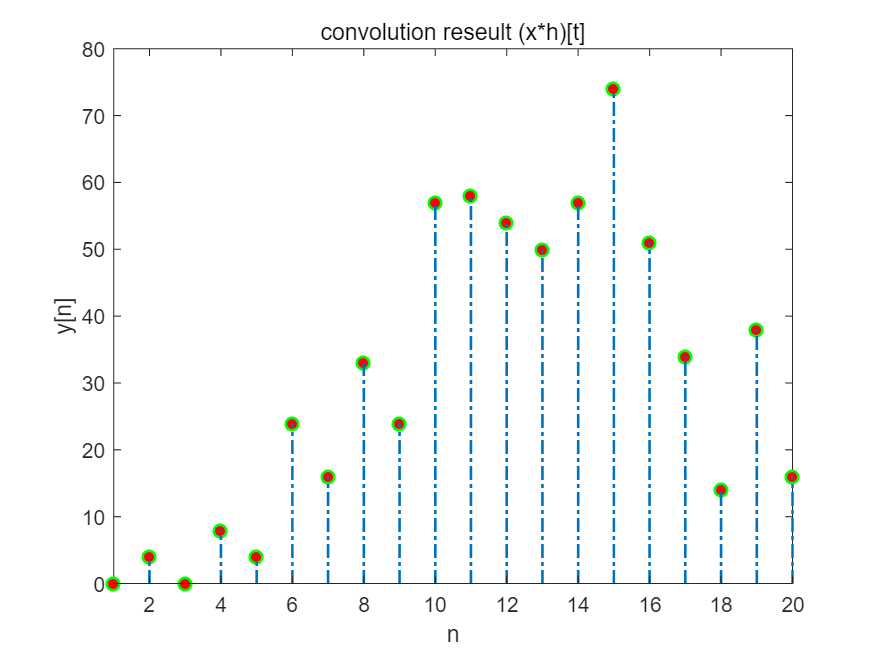

stem((1:20),y,'LineStyle','-.',...
    'LineWidth',1.25,...
     'MarkerFaceColor','red',...
     'MarkerEdgeColor','green') ;
    axis([1,20,0,80]);
    xlabel("n");
    ylabel("y[n]");
    title("convolution reseult (x*h)[t]");  